# Offline RL for GBWM — Week 7.0b: Continuous Stress Score in State (7D)

Week 7.0 (binary stress flag in state) showed: - The mechanism WORKS: Q-gap mean 2.24 (target was >0.02, 100x over). The network does use the 7th dim heavily. - Action distribution shifted in the partially-correct direction: defensive #1/#2 selected MORE in stress (+6.8pp, +9.2pp), aggressive #14 selected LESS in stress (-9.4pp). First time we see this signal. - BUT cross-seed instability exploded: Sharpe std 0.23 -> 0.55, with per-seed Q-gap ranging from 0.23 (seed 5000) to 6.67 (seed 4000). Mean Sharpe regressed 0.66 -> 0.54, worst Sharpe -6.37 -> -6.87.

Diagnosis: a binary feature is a sharp decision surface — different seeds latch onto qualitatively different uses of it (some heavily depend on it, others nearly ignore it), which produces the bimodal across-seed behavior. A SMOOTH input signal should provide more stable gradients across seeds and dampen this variance.

7.0b replaces the binary stress flag with a continuous stress score: stressScore(t) = max(0, VIX_z(t)) + max(0, -T10Y2Y_z(t)) stressNorm(t) = clip(stressScore(t) / stressP99, 0, 1) where stressP99 is the 99th percentile of stressScore over the train window. The normalized score is on [0, 1] so it matches the binary version's scale but provides smooth interpolation between regimes.

Same reward gate (binary BETA_HIGH/LOW from 6.1) is kept — only the state input changes vs 7.0. This isolates whether smoothness of the input signal alone fixes the across-seed instability.

clear; clc;

## Fixed Parameters (identical to 7.0)

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 3020;
horizonPeriods  = 30;
numEpisodes     = 200;
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week7_0b_state_stress_continuous");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

numEvalEpisodes = 30;
evalStepSize    = 30;

% Reward gate kept from 6.1 (binary β switch — only the STATE changes here)
BETA_HIGH = 8.0;
BETA_LOW  = 2.0;
DD_THR    = 0.03;

% Stress thresholds (for reward gate, kept binary, same as 6.1/7.0)
VIX_THR_Z   =  1.5;
SLOPE_THR_Z = -1.5;

% Macro column indices in z-scored matrix [DGS10_z, T10Y2Y_z, VIXCLS_z, DFF_z]
COL_T10Y2Y = 2;
COL_VIX    = 3;

% Q-gap diagnostic sample size
QGAP_NSAMPLES = 300;

## Load EXTENDED price data

pricesTT   = readtable("data/prices_train_extended.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load EXTENDED macro, z-score on extended train

macroTT   = readtable("data/macro_train_extended.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

## Load + z-score test data

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## Stress signals — binary (for reward gate) AND continuous (for state input)

Binary flag for the reward gate (unchanged from 6.1)

isStressDay_train = (M_train_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_train_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
trainStressRate   = mean(isStressDay_train(1:trainingRange));

isStressDay_test  = (M_test_z(:, COL_VIX) > VIX_THR_Z) | ...
                    (M_test_z(:, COL_T10Y2Y) < SLOPE_THR_Z);
testStressRate    = mean(isStressDay_test);

% NEW — continuous stress score (for state input).
% Normalized by train-only 99th percentile to live in [0, 1] like the binary
% version. Test scores are clipped using the same train-derived constant
% (no peeking into test for normalization).
stressScoreRaw_train = max(0, M_train_z(:, COL_VIX)) + ...
                        max(0, -M_train_z(:, COL_T10Y2Y));
stressScoreRaw_test  = max(0, M_test_z(:, COL_VIX)) + ...
                        max(0, -M_test_z(:, COL_T10Y2Y));

stressP99       = prctile(stressScoreRaw_train(1:trainingRange), 99);
if stressP99 < 1e-6
    stressP99 = 1;   % fallback
end
stressScore_train = min(stressScoreRaw_train / stressP99, 1);
stressScore_test  = min(stressScoreRaw_test  / stressP99, 1);

% Convenience accessor for the 7th dim
stressScoreOf = @(scoreVec, dayIdx) scoreVec(dayIdx);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2) + 1;   % still 7 (single continuous dim)

fprintf("=== Week 7.0b setup (continuous stress score in state) ===\n");

=== Week 7.0b setup (continuous stress score in state) ===


fprintf("  Observation dim    : %d  (binary flag REPLACED by continuous score)\n", obsDim);

  Observation dim    : 7  (binary flag REPLACED by continuous score)


fprintf("  Stress in state    : continuous in [0, 1]\n");

  Stress in state    : continuous in [0, 1]


fprintf("  Score formula      : max(0,VIX_z) + max(0,-T10Y2Y_z), normalized by train P99\n");

  Score formula      : max(0,VIX_z) + max(0,-T10Y2Y_z), normalized by train P99


fprintf("  Train stressP99    : %.4f (used to scale BOTH train and test scores)\n", stressP99);

  Train stressP99    : 4.3473 (used to scale BOTH train and test scores)


fprintf("  Train  score mean  : %.3f   median : %.3f   max : %.3f\n", ...
    mean(stressScore_train(1:trainingRange)), ...
    median(stressScore_train(1:trainingRange)), ...
    max(stressScore_train(1:trainingRange)));

  Train  score mean  : 0.171   median : 0.102   max : 1.000


fprintf("  Test   score mean  : %.3f   median : %.3f   max : %.3f\n", ...
    mean(stressScore_test), median(stressScore_test), max(stressScore_test));

  Test   score mean  : 0.504   median : 0.507   max : 1.000


fprintf("  Binary stress rate : train %.1f%%  test %.1f%%  (reward gate still uses binary)\n", ...
    100 * trainStressRate, 100 * testStressRate);

  Binary stress rate : train 11.0%  test 67.7%  (reward gate still uses binary)


fprintf("  Reward gate (kept) : beta = %.1f (stress)  /  %.1f (normal)\n", ...
    BETA_HIGH, BETA_LOW);

  Reward gate (kept) : beta = 8.0 (stress)  /  2.0 (normal)


## Cross-seed result storage (same fields as 7.0)

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);
results.actionHistStress = zeros(nSeeds, numActions);
results.actionHistNormal = zeros(nSeeds, numActions);
results.penaltyShare    = nan(nSeeds, 1);
results.meanPenaltyHigh = nan(nSeeds, 1);
results.meanPenaltyLow  = nan(nSeeds, 1);
results.qGapMean        = nan(nSeeds, 1);   % |Q(score=high) - Q(score=low)|
results.qGapMaxAction   = nan(nSeeds, 1);

allWealthPathsBySeed = cell(nSeeds, 1);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));
    else
        mkdir(seedLogsFolder);
    end

    % --- Uniform sliding start (no oversampling)
    stepSize      = max(1, floor((trainingRange - horizonPeriods) / numEpisodes));
    sampledStarts = (1 + (0:numEpisodes-1)' * stepSize);
    sampledStarts = sampledStarts(sampledStarts + horizonPeriods - 1 <= trainingRange);
    nEpThisSeed   = numel(sampledStarts);

    % --- Build offline episodes with regime-gated drawdown reward + 7D obs
    nPenaltyStepsHigh = 0;
    nPenaltyStepsLow  = 0;
    penaltySumHigh    = 0;
    penaltySumLow     = 0;
    sanityChecked     = false;

    % Pool of LOW-stress training obs for Q-gap diagnostic (we'll synthesize
    % high-stress twins by setting the 7th dim to a high reference value)
    qGapPool = nan(obsDim, 0);

    for episodeCount = 1:nEpThisSeed
        startIdx  = sampledStarts(episodeCount);
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        peakW  = initialWealth;

        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); ...
                        timeFrac(t); ...
                        macroVec; ...
                        stressScoreOf(stressScore_train, dayIdx)];

            if ~sanityChecked
                assert(numel(obs) == obsDim, "Obs dim mismatch (got %d, expected %d)", ...
                    numel(obs), obsDim);
                fprintf("  Sanity: first obs has %d elements; 7th dim = %.3f (continuous) — OK\n", ...
                    numel(obs), obs(end));
                sanityChecked = true;
            end

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            % Regime-gated penalty (reward gate stays binary, same as 6.1/7.0)
            stressFlag = isStressDay_train(dayIdx);
            betaT      = BETA_HIGH * stressFlag + BETA_LOW * ~stressFlag;

            peakW   = max(peakW, wealthNext);
            DD_t    = (peakW - wealthNext) / peakW;
            penalty = betaT * max(0, DD_t - DD_THR);
            reward  = log(wealthNext / wealth) - penalty;

            if penalty > 0
                if stressFlag
                    nPenaltyStepsHigh = nPenaltyStepsHigh + 1;
                    penaltySumHigh    = penaltySumHigh + penalty;
                else
                    nPenaltyStepsLow  = nPenaltyStepsLow + 1;
                    penaltySumLow     = penaltySumLow + penalty;
                end
            end

            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec; ...
                            stressScoreOf(stressScore_train, nextDayIdx)];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            % Collect low-stress obs (score < 0.1) for Q-gap diagnostic
            if obs(end) < 0.1 && size(qGapPool, 2) < QGAP_NSAMPLES
                qGapPool(:, end+1) = obs; %#ok<SAGROW>
            end

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
    end

    totalSteps = nEpThisSeed * horizonPeriods;
    nPenaltyAll = nPenaltyStepsHigh + nPenaltyStepsLow;
    results.penaltyShare(sIdx)    = nPenaltyAll / totalSteps;
    if nPenaltyStepsHigh > 0
        results.meanPenaltyHigh(sIdx) = penaltySumHigh / nPenaltyStepsHigh;
    else
        results.meanPenaltyHigh(sIdx) = 0;
    end
    if nPenaltyStepsLow > 0
        results.meanPenaltyLow(sIdx) = penaltySumLow / nPenaltyStepsLow;
    else
        results.meanPenaltyLow(sIdx) = 0;
    end
    fprintf("  Saved %d episodes (%d steps). Penalty: stress %d (avg %.4f) / normal %d (avg %.4f)\n", ...
        nEpThisSeed, totalSteps, ...
        nPenaltyStepsHigh, results.meanPenaltyHigh(sIdx), ...
        nPenaltyStepsLow, results.meanPenaltyLow(sIdx));

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent (7D input) ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...
        Verbose          = false);
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Q-gap diagnostic: does the network react to the continuous score? ---
    % Take low-stress obs (score<0.1) and synthesize high-stress twins by
    % setting the 7th dim to 1.0 (the cap of the normalized score).
    if size(qGapPool, 2) > 0
        trainedCritic = getCritic(agent);
        sampleObsLow  = qGapPool;
        sampleObsHigh = sampleObsLow;
        sampleObsHigh(end, :) = 1.0;

        nSamp = size(sampleObsLow, 2);
        Qlow  = nan(numActions, nSamp);
        Qhigh = nan(numActions, nSamp);
        for k = 1:nSamp
            Qlow(:, k)  = getValue(trainedCritic, {sampleObsLow(:, k)});
            Qhigh(:, k) = getValue(trainedCritic, {sampleObsHigh(:, k)});
        end
        qGapAbs = abs(Qhigh - Qlow);
        results.qGapMean(sIdx)      = mean(qGapAbs, 'all');
        results.qGapMaxAction(sIdx) = max(mean(qGapAbs, 2));

        fprintf("  Q-gap diagnostic (%d samples, score 0->1): mean %.4f | max-per-action %.4f\n", ...
            nSamp, results.qGapMean(sIdx), results.qGapMaxAction(sIdx));
    else
        fprintf("  Q-gap diagnostic skipped (no low-stress samples collected)\n");
    end

    % --- Hold-out evaluation (7D obs) ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);
    allActionStressFlag = false(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); ...
                          timeFrac(t); ...
                          macroVec; ...
                          stressScoreOf(stressScore_test, dayIdx)] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            allActionStressFlag(ep, t) = isStressDay_test(dayIdx);
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);

    flatActions = allActions(:);
    flatStress  = allActionStressFlag(:);
    for a = 1:numActions
        results.actionHist(sIdx, a)        = sum(flatActions == a);
        results.actionHistStress(sIdx, a)  = sum(flatActions == a &  flatStress);
        results.actionHistNormal(sIdx, a)  = sum(flatActions == a & ~flatStress);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Sanity: first obs has 7 elements; 7th dim = 0.061 (continuous) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 340 (avg 0.3989) / normal 1071 (avg 0.0544)


  Q-gap diagnostic (300 samples, score 0->1): mean 1.1321 | max-per-action 1.3062


  Success 13/30 | Sharpe 0.26±2.92 | MaxDD 7.82%±6.87% | TermW 99576 (P10 87164)



========== Seed 2000 (2/5) ==========


  Sanity: first obs has 7 elements; 7th dim = 0.061 (continuous) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 301 (avg 0.4709) / normal 1170 (avg 0.0547)


  Q-gap diagnostic (300 samples, score 0->1): mean 0.1238 | max-per-action 0.1728


  Success 10/30 | Sharpe 0.13±2.78 | MaxDD 7.06%±7.57% | TermW 98798 (P10 91438)



========== Seed 3000 (3/5) ==========


  Sanity: first obs has 7 elements; 7th dim = 0.061 (continuous) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 329 (avg 0.4201) / normal 1241 (avg 0.0592)


  Q-gap diagnostic (300 samples, score 0->1): mean 5.2388 | max-per-action 5.5763


  Success 16/30 | Sharpe 1.00±3.24 | MaxDD 13.88%±8.45% | TermW 106426 (P10 85865)



========== Seed 4000 (4/5) ==========


  Sanity: first obs has 7 elements; 7th dim = 0.061 (continuous) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 325 (avg 0.3331) / normal 1298 (avg 0.0612)


  Q-gap diagnostic (300 samples, score 0->1): mean 1.9405 | max-per-action 2.0747


  Success 16/30 | Sharpe 0.86±3.04 | MaxDD 13.17%±7.05% | TermW 105700 (P10 86509)



========== Seed 5000 (5/5) ==========


  Sanity: first obs has 7 elements; 7th dim = 0.061 (continuous) — OK


  Saved 200 episodes (6000 steps). Penalty: stress 340 (avg 0.4701) / normal 1092 (avg 0.0526)


  Q-gap diagnostic (300 samples, score 0->1): mean 1.9995 | max-per-action 2.1271


  Success 14/30 | Sharpe 0.62±2.82 | MaxDD 6.87%±5.23% | TermW 100524 (P10 91924)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) — Week 7.0b continuous stress score in state =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) — Week 7.0b continuous stress score in state =====


fprintf("Train range          : 2010-01 -> 2021-12  (%d days)\n", trainingRange);

Train range          : 2010-01 -> 2021-12  (3020 days)


fprintf("State dim            : %d  (continuous stress score in [0, 1] appended)\n", obsDim);

State dim            : 7  (continuous stress score in [0, 1] appended)


fprintf("Reward gate (kept)   : beta = %.1f (stress) / %.1f (normal)   DD_THR = %.3f\n", ...
    BETA_HIGH, BETA_LOW, DD_THR);

Reward gate (kept)   : beta = 8.0 (stress) / 2.0 (normal)   DD_THR = 0.030


fprintf("Penalty-active share : %.1f%% of training steps (avg)\n", ...
    100*mean(results.penaltyShare));

Penalty-active share : 25.0% of training steps (avg)


fprintf("Penalty avg magn     : stress %.4f  /  normal %.4f   (6.1: 0.4186 / 0.0564)\n", ...
    mean(results.meanPenaltyHigh), mean(results.meanPenaltyLow));

Penalty avg magn     : stress 0.4186  /  normal 0.0564   (6.1: 0.4186 / 0.0564)


fprintf("Q-gap (state effect) : mean %.4f  |  max-per-action %.4f   (7.0 binary: 2.24 | 2.66)\n", ...
    mean(results.qGapMean, 'omitnan'), mean(results.qGapMaxAction, 'omitnan'));

Q-gap (state effect) : mean 2.0869  |  max-per-action 2.2514   (7.0 binary: 2.24 | 2.66)


fprintf("Success rate         : %.1f / %d  (std %.2f)   <-- 6.1: 14.6  | 7.0: 13.6\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 13.8 / 30  (std 2.49)   <-- 6.1: 14.6  | 7.0: 13.6


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)   <-- 6.1: 0.66 (0.23) | 7.0: 0.54 (0.55)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.57 (across-seed std 0.37)   <-- 6.1: 0.66 (0.23) | 7.0: 0.54 (0.55)


fprintf("Within-seed Sharpe std : %.2f (avg)\n", mean(results.stdSharpe));

Within-seed Sharpe std : 2.96 (avg)


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)   <-- 6.1: 7.78%% | 7.0: 8.40%%\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 9.76% (across-seed std 3.46%)   <-- 6.1: 7.78% | 7.0: 8.40%


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)   <-- 6.1: 101633 | 7.0: 101006\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 102205 (across-seed std 3584)   <-- 6.1: 101633 | 7.0: 101006


fprintf("Terminal P10 (avg)   : %.0f   <-- 6.1: 89758 | 7.0: 91387\n", mean(results.p10TermWealth));

Terminal P10 (avg)   : 88580   <-- 6.1: 89758 | 7.0: 91387


fprintf("Worst Sharpe (avg)   : %.2f   <-- 6.1: -6.37 | 7.0: -6.87 | Plan C: -5.38\n", ...
    mean(results.minSharpe));

Worst Sharpe (avg)   : -6.56   <-- 6.1: -6.37 | 7.0: -6.87 | Plan C: -5.38


fprintf("MaxDD P90 (avg)      : %.2f%%   <-- 6.1: 15.75%% | 7.0: 16.88%% | Plan C: 11.79%%\n", ...
    mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 19.80%   <-- 6.1: 15.75% | 7.0: 16.88% | Plan C: 11.79%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | Q-gap\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10) | Q-gap


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f | %.4f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx), ...
        results.qGapMean(sIdx));
end

1000 |   13 |  0.26 ± 2.92    |  7.82% ± 6.87%  | 99576 / 87164 | 1.1321
2000 |   10 |  0.13 ± 2.78    |  7.06% ± 7.57%  | 98798 / 91438 | 0.1238
3000 |   16 |  1.00 ± 3.24    | 13.88% ± 8.45%  | 106426 / 85865 | 5.2388
4000 |   16 |  0.86 ± 3.04    | 13.17% ± 7.05%  | 105700 / 86509 | 1.9405
5000 |   14 |  0.62 ± 2.82    |  6.87% ± 5.23%  | 100524 / 91924 | 1.9995



fprintf("\n--- Action histogram (all eval steps) ---\n");


--- Action histogram (all eval steps) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :   58 (1.3%)
  action  2 :   82 (1.8%)
  action  3 :   63 (1.4%)
  action  4 :    4 (0.1%)
  action  5 :  491 (10.9%)
  action  6 :    6 (0.1%)
  action  7 :  545 (12.1%)
  action  8 :   64 (1.4%)
  action  9 :  793 (17.6%)
  action 10 :  205 (4.6%)
  action 11 :  269 (6.0%)
  action 12 :  179 (4.0%)
  action 13 :  102 (2.3%)
  action 14 :   84 (1.9%)
  action 15 : 1555 (34.6%)



% Core diagnostic — stress vs normal action split
fprintf("\n--- Action histogram split by TEST regime (vs 6.1 / 7.0 comparison) ---\n");


--- Action histogram split by TEST regime (vs 6.1 / 7.0 comparison) ---


totalStress = sum(results.actionHistStress, 1);
totalNormal = sum(results.actionHistNormal, 1);
sumS = sum(totalStress); sumN = sum(totalNormal);
fprintf("action |  stress%%  |  normal%%  |  diff (pp)\n");

action |  stress%  |  normal%  |  diff (pp)


for a = 1:numActions
    if totalStress(a) + totalNormal(a) > 0
        pS = 100 * totalStress(a) / max(sumS, 1);
        pN = 100 * totalNormal(a) / max(sumN, 1);
        marker = "";
        if abs(pS - pN) >= 5
            marker = "  <-- diverges";
        end
        fprintf("  %2d   |  %5.1f    |  %5.1f    |  %+5.1f%s\n", ...
            a, pS, pN, pS - pN, marker);
    end
end

   1   |    0.6    |    3.5    |   -3.0
   2   |    2.3    |    0.3    |   +2.1
   3   |    1.2    |    2.0    |   -0.8
   4   |    0.1    |    0.0    |   +0.1
   5   |   10.2    |   13.1    |   -2.9
   6   |    0.1    |    0.4    |   -0.3
   7   |   12.6    |   10.5    |   +2.1
   8   |    1.4    |    1.4    |   -0.0
   9   |   20.7    |    8.1    |  +12.7  <-- diverges
  10   |    2.9    |    9.8    |   -6.9  <-- diverges
  11   |    5.4    |    7.7    |   -2.3
  12   |    4.1    |    3.7    |   +0.4
  13   |    1.0    |    6.1    |   -5.0  <-- diverges
  14   |    1.5    |    2.9    |   -1.4
  15   |   35.8    |   30.6    |   +5.3  <-- diverges



fprintf("\nInterpretation hints:\n");


Interpretation hints:


fprintf("  - Hypothesis: smooth signal -> stable Q-gap across seeds -> lower Sharpe std\n");

  - Hypothesis: smooth signal -> stable Q-gap across seeds -> lower Sharpe std


fprintf("  - Target: across-seed Sharpe std <= 0.30 (7.0 was 0.55), Q-gap std also tight\n");

  - Target: across-seed Sharpe std <= 0.30 (7.0 was 0.55), Q-gap std also tight


fprintf("  - Ideal direction (still): stress -> defensive (#1/#2/#3/#11)\n");

  - Ideal direction (still): stress -> defensive (#1/#2/#3/#11)


fprintf("  - If across-seed std still > 0.4, the binary->continuous switch alone isn't enough\n");

  - If across-seed std still > 0.4, the binary->continuous switch alone isn't enough


## Plot — aggregated wealth band across all seeds

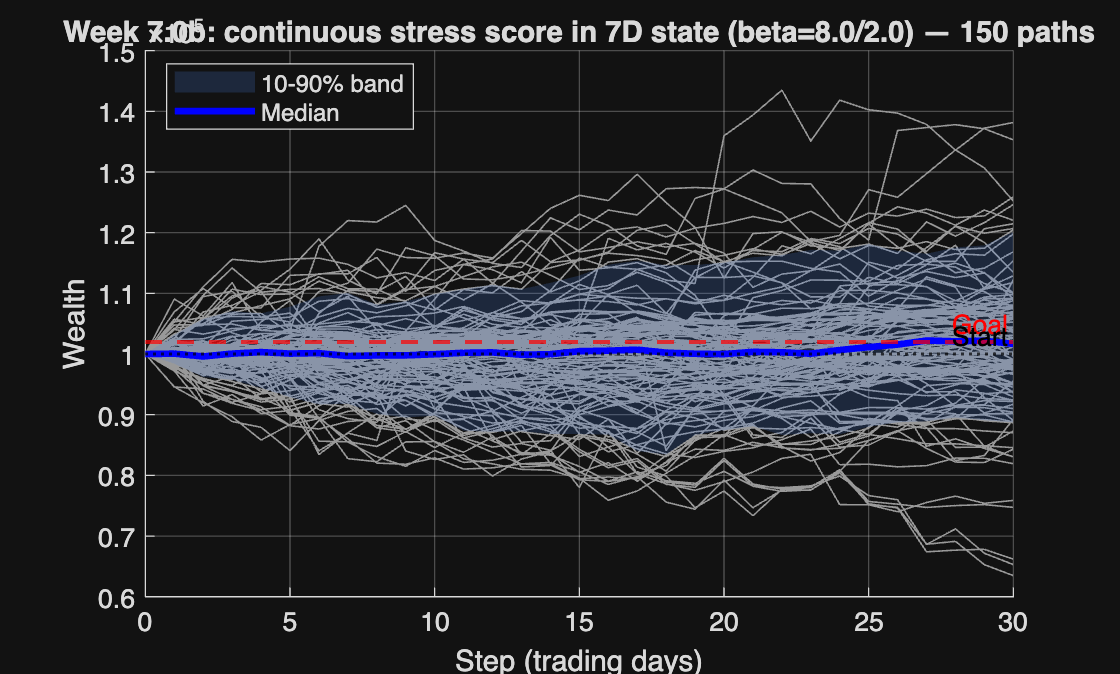

figure('Name','Hold-out wealth paths (Week 7.0b continuous stress in 7D state)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Week 7.0b: continuous stress score in 7D state (beta=%.1f/%.1f) — %d paths', ...
    BETA_HIGH, BETA_LOW, rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end